f = figure("Name",'PLotRobot')

f =   Figure (1: PLotRobot) with properties:

      Number: 1
        Name: 'PLotRobot'
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


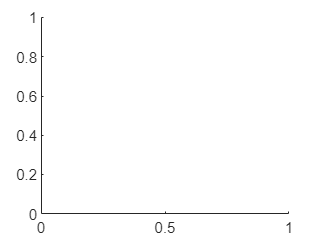

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



ax = axes("Parent",f)


n=10

n = 10

theta = linspace(0,2*pi,n);

S = [cos(theta);sin(theta);zeros(2,n)];


A0 = tform(eye(3),zeros(1,3))

A0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


A01 = tform(eye(3),[0;0;1])^-1

A01 =      1     0     0     0
     0     1     0     0
     0     0     1    -1
     0     0     0     1


% A12 = tform(rotzd(45),[0;0;1])
% A02 = A01*A12

S0 = A0*S;
S1 = A01*S

S1 =     1.0000    0.7660    0.1736   -0.5000   -0.9397   -0.9397   -0.5000    0.1736    0.7660    1.0000
         0    0.6428    0.9848    0.8660    0.3420   -0.3420   -0.8660   -0.9848   -0.6428   -0.0000
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0



[X,Y,Z] = combineSection(S0,S1)

%m = mesh(ax,X,Y,Z)
